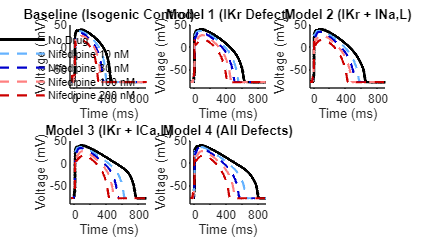

Processing Baseline (Isogenic Control)...
Processing Model 1 (IKr Defect)...
Processing Model 2 (IKr + INa,L)...
Processing Model 3 (IKr + ICa,L)...
Processing Model 4 (All Defects)...


% Script: Drug_Challenge_AP_Overlays.m
% Generates AP morphology overlays for 5 Models across 5 Drug Conditions
close all; clear; clc;

% Load initial conditions and the original baseline parameters
load ICs_baseline;
load baseline_parameter_inputs;

% Store a clean copy of the baseline parameters
original_baseline_params = baseline_parameter_inputs;

% ========================================================================
%  START: EXPERIMENTAL CONFIGURATION 
% ========================================================================

num_models = 5;
model_names = {'Baseline (Isogenic Control)', 'Model 1 (IKr Defect)', ...
               'Model 2 (IKr + INa,L)', 'Model 3 (IKr + ICa,L)', ...
               'Model 4 (All Defects)'};

% Define the 5 drug conditions to test for each model
% drug_type: 0 = No Drug, 1 = Mexiletine, 2 = Nifedipine
drug_types = [0, 2, 2, 2, 2]; 
drug_doses = [0, 10, 30 100, 200]; % uM for Mex, nM for Nif
drug_labels = {'No Drug', 'Nifedipine 10 nM', ...
               'Nifedipine 30 nM','Nifedipine 100 nM', 'Nifedipine 200 nM'};

% Colors for traces: Black (No drug), Light/Dark Blue (Mex), Light/Dark Red (Nif)
trace_colors = [0 0 0; 0.4 0.7 1; 0 0 0.8; 1 0.5 0.5; 0.8 0 0];

% Setup Figure
figure('Name', 'Drug Challenge AP Overlays', 'Color', 'w', 'Position', [100, 100, 1400, 800]);

% ========================================================================
%  START: BATCH SIMULATION BLOCK
% ========================================================================

% Loop through each model from 0 (Baseline) to 4
for model_id = 0:(num_models - 1)
    
    fprintf('Processing %s...\n', model_names{model_id + 1});
    
    % Select subplot for the current model
    subplot(2, 3, model_id + 1);
    hold on;
    
    % Loop through the 5 drug conditions for this specific model
    for cond = 1:length(drug_types)
        
        current_drug = drug_types(cond);
        current_dose = drug_doses(cond);
        
        % --- 1. Reset parameters ---
        modified_params = original_baseline_params;
        modified_params(83) = 1; % Pacing ON
        
        % Store baseline persistent values before modification
        baseline_C_persist_CaL = modified_params(86);
        baseline_C_persist_NaL = modified_params(87);
        
        % Standard Kernik-Clancy Mature adjustments
        modified_params(1) = modified_params(1) * 5;     % g_K1
        modified_params(7) = modified_params(7) * 1.45;  % g_Na
        
        % --- 2. Apply Disease Model Modifications ---
        if model_id == 1
            modified_params(2) = modified_params(2) * (1 - 0.725); % IKr
        elseif model_id == 2
            modified_params(2) = modified_params(2) * (1 - 0.725);
            modified_params(87) = baseline_C_persist_NaL * 2.31 * 3; % INaL
        elseif model_id == 3
            modified_params(2) = modified_params(2) * (1 - 0.725);
            modified_params(86) = baseline_C_persist_CaL * 2.29; % ICaL
        elseif model_id == 4
            modified_params(2) = modified_params(2) * (1 - 0.725);
            modified_params(87) = baseline_C_persist_NaL * 2.31 * 3;
            modified_params(86) = baseline_C_persist_CaL * 2.29;
        end
        
        % --- 3. Apply Drug Block ---
        if current_drug == 1 % MEXILETINE
            IC50_Mex_INa_peak = 40; % uM
            IC50_Mex_INa_late = 10; % uM
            
            fract_cond_INa_peak = 1 / (1 + (current_dose / IC50_Mex_INa_peak));
            fract_cond_INa_late = 1 / (1 + (current_dose / IC50_Mex_INa_late));
            
            modified_params(7) = modified_params(7) * fract_cond_INa_peak;
            modified_params(87) = modified_params(87) * fract_cond_INa_late;
            
        elseif current_drug == 2 % NIFEDIPINE
            IC50_Nif_ICaL = 15; % nM
            fract_cond_ICaL = 1 / (1 + (current_dose / IC50_Nif_ICaL));
            
            % Applied to primary L-type Ca channel (index 5)
            % per original script, persistent ICaL is left unblocked
            modified_params(5) = modified_params(5) * fract_cond_ICaL;
        end
        
        % --- 4. Run ODE Simulation ---
        options = odeset('MaxStep',1,'InitialStep',2e-2);
        run_time = 30e3; % 6000 ms to ensure steady state beat capturing
        [Time, values] = ode15s(@ipsc_function,[0, run_time], Y_init, options, modified_params);
        
        Vm = values(:,1);
        
        % --- 5. Extract Beat & Align (0ms - 5000ms window) ---
        inds_time_start = find(Time > 8000, 1, 'first');
        inds_time_end   = find(Time > 13000, 1, 'first');
        
        beat_time_raw = Time(inds_time_start:inds_time_end);
        beat_vm_raw   = Vm(inds_time_start:inds_time_end);
        
        % Calculate Stats (to get t_depol for alignment)
        results = calculate_ap_stats(beat_time_raw, beat_vm_raw);
        aligned_time = beat_time_raw - results.t_depol;
        
        % --- 6. Plot Trace ---
        if current_drug == 0
            line_style = '-';     % Solid line for No Drug control
            line_width = 2.0;     % Thicker line to stand out
        else
            line_style = '--';    % Dashed line for all Drug conditions
            line_width = 1.5;     % Standard width
        end
        
        plot(aligned_time, beat_vm_raw, 'Color', trace_colors(cond,:), ...
            'LineStyle', line_style, 'LineWidth', line_width);
        
    end
    
    % Format Subplot
    title(model_names{model_id + 1});
    xlabel('Time (ms)');
    ylabel('Voltage (mV)');
    xlim([-50 900]); 
    ylim([-90 50]);
    set(gca, 'box', 'off', 'tickdir', 'out');
    
    % Add legend only to the first subplot to save space
    if model_id == 0
        legend(drug_labels, 'Location', 'northeast');
        legend boxoff;
    end
    
    hold off;
end


% ========================================================================
%  HELPER FUNCTION: Calculate AP Morphology
% ========================================================================

function results = calculate_ap_stats(time, voltage)
    % Calculates AP stats for a single beat
    
    % 1. Derivatives for Upstroke
    dV = diff(voltage);
    dt = diff(time);
    dVdt = dV ./ dt; % mV/ms = V/s
    
    [dVdt_max, idx_max_diff] = max(dVdt);
    t_depol = time(idx_max_diff);
    
    % 2. Peak Voltage (Search only after upstroke)
    [V_max, idx_peak_local] = max(voltage(idx_max_diff:end));
    idx_peak = idx_peak_local + idx_max_diff - 1;
    
    % 3. Resting Potential (Take mean of first few points before upstroke)
    if idx_max_diff > 10
        RMP = mean(voltage(1:10));
    else
        RMP = voltage(1);
    end
    
    APA = V_max - RMP;
    
    % 4. APD Calculations
    get_apd = @(pct) interp1(voltage(idx_peak:end), time(idx_peak:end), V_max - (pct/100)*APA, 'linear', NaN) - t_depol;
    
    results.APD90 = get_apd(90);
    results.APD50 = get_apd(50);
    results.APD30 = get_apd(30);  
    results.dVdt_max = dVdt_max;
    results.APA = APA;
    results.RMP = RMP;
    results.V_max = V_max;        
    results.t_depol = t_depol;
end